# ECSE 343:Assignment 5

Name: Deniz Karakus

Student Id. 261114510

Due Date: 15 April 2025

## Question 1

 You are given the following 3rd order differential equation,

                
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(\frac{\pi t} {4})$$


a. Transform the above differential equation into a system of first-order differential equations. **(5 marks)**

**let x1(t) = y(t), x2(t) = y'(t), x3(t) = y''(t). This means x1'(t) = x2(t), x2'(t) = x3(t) and x3'(t) = y'''(t). Subbing x1, x2 and x3 into our equation, we get x3'(t) = -32x3(t) - 61.25x2(t) - 37.5x1(t) + sin(pi*t/4). We end up with the system of first-order ODEs:**

**x1'(t) = x2(t) **

**x2'(t) = x3(t)**

**x3'(t) =  -32x3(t) - 61.25x2(t) - 37.5x1(t) + sin(pi*t/4)**

b.  For the system of first order ODEs obtained in part a, apply the Backward Euler approximation for the derivative and write the obtained **difference Equations **below. **(5 marks)**

**let h be step size, and let x1,n , x2,n, and x3,n be the values at time step n. We obtain the following equations using Backward Euler approx:**

**x1,n+1 = x1,n + hx2,n+1**

**x2,n+1 = x2,n + hx3,n+1**

**(1+32*h)*x3,n+1+61.25h*x2,n+1+37.5h*x1,n+1=x3,n+h*sin((pi*tn+1)/4)**

c.  You are provided with the initial conditions, $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$ for the given differential equation.  Use the cell below to implement the Backward Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  

Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

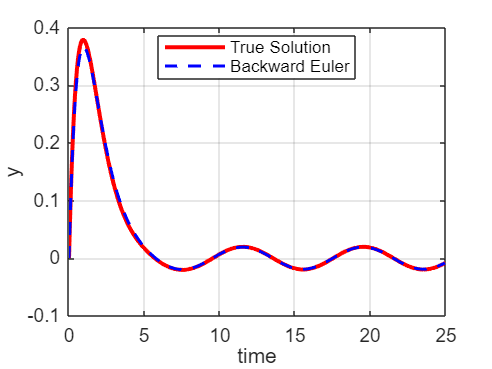


clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% we said x1 = y, x2 = y' and x3 = y''
x1 = 0;
x2 = 1; 
x3 = 0;

N = length(T);
x1_vector = zeros(1,N);
x2_vector = zeros(1,N);
x3_vector = zeros(1,N);

x1_vector(1) = x1;
x2_vector(1) = x2;
x3_vector(1) = x3;

for n = 1 : N-1
    t_next = T(n+1);
    %set up our system 
     A = [1, -dT, 0;
     0, 1, -dT;
     37.5*dT, 61.25*dT, 1 + 32*dT];
     
    B = [x1_vector(n);
         x2_vector(n);
         x3_vector(n) + dT * sin(pi * t_next / 4)];

    %solve
    x_next = A \ B;
    x1_vector(n+1) = x_next(1);
    x2_vector(n+1) = x_next(2);
    x3_vector(n+1) = x_next(3);
end
y = x1_vector;











%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

d.  Run the code you wrote in part c again, run the code for $25s$ and use the time step $\Delta t= 1s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

 Is the obtained solution more accurate than the solution in part c? Explain.  **(2 marks)**

*Note: You may copy the code you wrote in part c in the cell below to run it for *$\Delta t =1s$ 

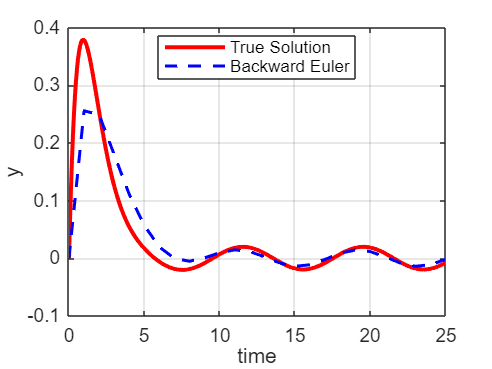

% you may copy the code from part c here and run it for deltaT =1s
clear all
dT = 1; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% we said x1 = y, x2 = y' and x3 = y''
x1 = 0;
x2 = 1; 
x3 = 0;

N = length(T);
x1_vector = zeros(1,N);
x2_vector = zeros(1,N);
x3_vector = zeros(1,N);

x1_vector(1) = x1;
x2_vector(1) = x2;
x3_vector(1) = x3;

for n = 1 : N-1
    t_next = T(n+1);
    %set up our system 
     A = [1, -dT, 0;
     0, 1, -dT;
     37.5*dT, 61.25*dT, 1 + 32*dT];
     
    B = [x1_vector(n);
         x2_vector(n);
         x3_vector(n) + dT * sin(pi * t_next / 4)];

    %solve
    x_next = A \ B;
    x1_vector(n+1) = x_next(1);
    x2_vector(n+1) = x_next(2);
    x3_vector(n+1) = x_next(3);
end
y = x1_vector;











%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

**no, the solution is not more accurate than the solution in part c). This is because the global error for backwards euler is proportionate to the size of the time step. When we increase the time step to 1s, its too large and we cant capture the oscillatory behaviour of the solution. This results in the increased error that we can see visually in our graph. **

e. For the system of first-order ODEs obtained in part a, use the Forward Euler approximation for the derivative and write the obtained difference Equations below. **(5 marks)**

**starting with our first order equations from before:**

**x1'(t) = x2(t) **

**x2'(t) = x3(t)**

**x3'(t) =  -32x3(t) - 61.25x2(t) - 37.5x1(t) + sin(pi*t/4)**

**forward euler method : xn+1 = xn + h*f(tn, xn)**

**now, we apply forward euler to this **

**x1,n+1 = x1,n + h*x2,n **

**x2, n+1 = x2,n + h*x3,n**

**x3,n+1=x3,n+h*(−32x3,n−61.25x2,n−37.5x1,n+sin(pi*tn/4))**

f. Use the same initial conditions as part c (i.e. $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$).  Implement the Forward  Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

Write your code in the cell below.

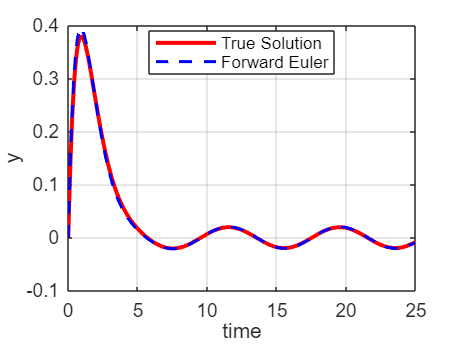

clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

x1 = 0;  % y(0)
x2 = 1;  % y'(0)
x3 = 0;  % y''(0)

N = length(T);
x1_vector = zeros(1,N);
x2_vector = zeros(1,N);
x3_vector = zeros(1,N);

x1_vector(1) = x1;
x2_vector(1) = x2;
x3_vector(1) = x3;

for n = 1:N-1
    t_now = T(n);
    
    x1_next = x1_vector(n) + dT * x2_vector(n);
    x2_next = x2_vector(n) + dT * x3_vector(n);
    x3_next = x3_vector(n) + dT * (-32*x3_vector(n) - 61.25*x2_vector(n) - 37.5*x1_vector(n) + sin(pi*t_now/4));
    
    x1_vector(n+1) = x1_next;
    x2_vector(n+1) = x2_next;
    x3_vector(n+1) = x3_next;
end

y = x1_vector;




%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Forward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

g. Run the code you wrote in part f again, run the code for $25s$ and use the time step $\Delta t= 0.068s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

*Note: You may copy the code you wrote in part f in the cell below to run it for *$\Delta t =0.068s$ 

Comment on the solutions obtained in part e and f. **(2 marks)**

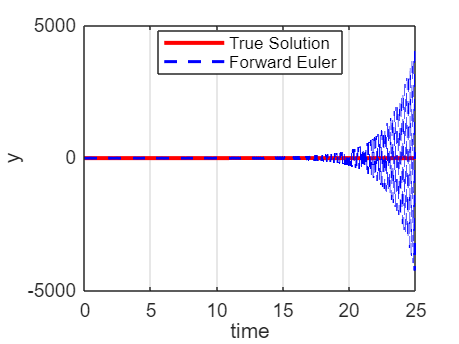

% you may copy the code from part c here and run it for deltaT =1s
clear all
dT = 0.068; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

x1 = 0;  % y(0)
x2 = 1;  % y'(0)
x3 = 0;  % y''(0)

N = length(T);
x1_vector = zeros(1,N);
x2_vector = zeros(1,N);
x3_vector = zeros(1,N);

x1_vector(1) = x1;
x2_vector(1) = x2;
x3_vector(1) = x3;

for n = 1:N-1
    t_now = T(n);
    
    x1_next = x1_vector(n) + dT * x2_vector(n);
    x2_next = x2_vector(n) + dT * x3_vector(n);
    x3_next = x3_vector(n) + dT * (-32*x3_vector(n) - 61.25*x2_vector(n) - 37.5*x1_vector(n) + sin(pi*t_now/4));
    
    x1_vector(n+1) = x1_next;
    x2_vector(n+1) = x2_next;
    x3_vector(n+1) = x3_next;
end

y = x1_vector;




%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Forward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

**in part f, where we had delta t = 0.065s, the forward euler method gave an accurate solution to our system. At delta t = 0.068s, our forward euler method becomes unstable and grows exponentially, diverging from the actual solution due to the stiff nature of our system. This shows that the forward euler method is conditionally stable and highlights the importance of step size selection for explicit methods. **

**Question 2: **

 The circuit shown below is called the Half-Wave Rectifier. For this circuit we will compute the transient response of the circuit for all the voltage nodes, namely, V1, V2 and V3.  

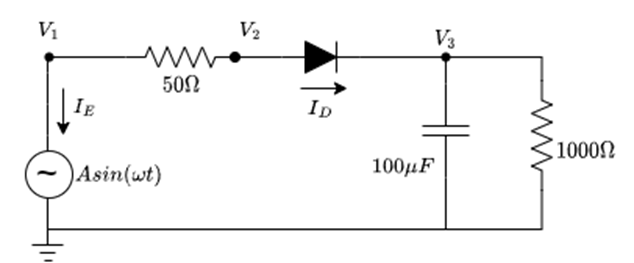

IE is the current passing into voltage source. ID is the diode current shown as 


$$I_D =I_{S\;} \left(e^{\frac{\left(V_2 -V_3 \right)}{\textrm{Vt}\;}} -1\right)$$


 Is is the saturation current of the diode and $V_t$ is the thermal voltage. As we can see that the diode current is a nonlinear function of the node voltages $V_2$ and $V_3$, this makes the nodal equations of the above circuit is nonlinear.

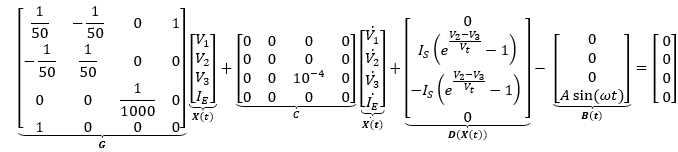

The above equation can be written in compact form as, 


$$\mathit{\mathbf{F}}\left(\mathit{\mathbf{X}}\left(t\right)\right)=\mathit{\mathbf{G}}\;\mathit{\mathbf{X}}\left(t\right)+\mathit{\mathbf{C}}\;\dot{\mathit{\mathbf{X}}\left(\mathit{\mathbf{t}}\right)} +\mathit{\mathbf{D}}\left(\mathit{\mathbf{X}}\left(\mathit{\mathbf{t}}\right)\right)-\mathit{\mathbf{B}}\left(t\right)=0$$


The expression in (3) represents system of Nonlinear Differential Algebraic equations. The solution vector $\textbf{X}(t)$  and the input vector $\textbf{B}(t)$  are time varying.  At time,  ,  $\textbf{X}(t)$ and $\textbf{B}(t)$ can be written as $\textbf{X}_n$ and $\textbf{B}_n$, respectively.

 
$$\mathit{\mathbf{F}}\left({\mathit{\mathbf{X}}}_n \right)=\mathit{\mathbf{G}}\;{\mathit{\mathbf{X}}}_n +\mathit{\mathbf{C}}\;\dot{{\mathit{\mathbf{X}}}_n } +\mathit{\mathbf{D}}\left({\mathit{\mathbf{X}}}_n \right)-{\mathit{\mathbf{B}}}_n =0$$


Use the Backward Euler formula and the Newton-Raphson method to find the transient solution for this circuit. The use transient voltage source with amplitude equal to 5V with the frequency of 60Hz. Use saturation current for the diode, $I_S = 10^{-13} A$ and the thermal voltage of the diode, $V_t = 0.025 V$. Simulate, the circuit for 0.5s with the time step, $\Delta t = 10^{-4}s$  Use the tolerance value, $\epsilon_{tol} = 10^{-5}$, to check for convergence of the Newton-Raphson. Plot the obtained solution for $V_1$,$V_2$, and $V_3$

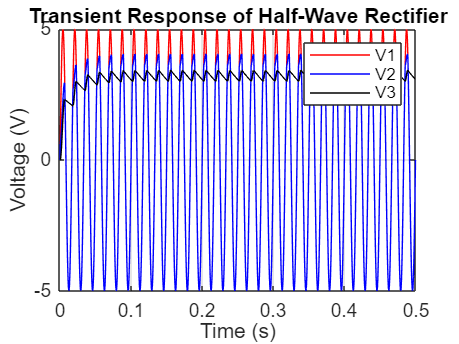

% write your code below. you can also use the appendix to write any
% functions if necessary
%constants
dt = 1e-4;
Tmax = 0.5;
time = 0:dt:Tmax;
f = 60;
A = 5; %amplitude
Is = 1e-13; %saturation current
Vt = 0.025; %thermal voltage
tol = 1e-5;

% Matrices
G = [1/50, -1/50,   0,     1;
    -1/50, 1/50,    0,     0;
     0,     0,     1/1000, 0;
     1,     0,      0,     0];

C = [0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 100e-6, 0;
     0, 0, 0, 0];

%Initial conditions
X = zeros(4, length(time)); % X = [V1; V2; V3; IE]
X_prev = X(:,1);

%Simulation loop
for n = 2:length(time)
    t = time(n);
    B = [0; 0; 0; A*sin(2*pi*f*t)];
    
    %Newton-Raphson initialization
    X_guess = X_prev;
    for iter = 1:100
        %Diode current and Jacobian
        V2 = X_guess(2); V3 = X_guess(3);
        ID = Is * (exp((V2 - V3)/Vt) - 1);
        dID = Is / Vt * exp((V2 - V3)/Vt); %derivative of ID wrt (V2 - V3)

        %D(X)
        Dvec = [0; ID; -ID; 0];
        
        %F(X)
        F = G*X_guess + C*(X_guess - X_prev)/dt + Dvec - B;

        %Jacobian of D
        Jd = [0,  0,   0,  0;
              0, dID, -dID, 0;
              0, -dID, dID, 0;
              0,  0,   0,  0];

        %Jacobian of full system
        J = G + C/dt + Jd;

        %Newton-Raphson update
        delta = -J \ F;
        X_guess = X_guess + delta;

        if norm(delta, inf) < tol
            break;
        end
    end
    X(:,n) = X_guess;
    X_prev = X_guess;
end

% Plot V1, V2, V3
figure;
plot(time, X(1,:), 'r', 'DisplayName', 'V1'); hold on;
plot(time, X(2,:), 'b', 'DisplayName', 'V2');
plot(time, X(3,:), 'k', 'DisplayName', 'V3');
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Transient Response of Half-Wave Rectifier');
legend;
grid on;

## Question 3 :  

a. Write  steepest descent algorithm to solve  linear system of equations given by  $\textbf A \textbf x = \textbf b$,  where $\textbf A \in \mathbb{R}^{n \times n}$ is a symmetric and positive definite matrix, $\textbf b \in \mathbb{R}^{n \times 1}$ and $\textbf x \in \mathbb{R}^{n \times 1}$. You can implement the maethod in the appendix. (10 marks)

% Write your code in the appendix.

b. In this question, you will solve the matrix systems of size ranging for n= 2, 3, 4 , 5, ..., 100 .  Use the function named *getSystemMatrix_with_lowerConditionNumber* (provided in the appendix) to  generate the system matrix $\textbf A$ and the vector $\textbf b$ of  size n.  The matrix $\textbf A$ generated by the *getSystemMatrix.m* has a good condition number.

Use the LU decomposition based method( you wrote in earlier assignments ) and the steepest descent method  to compute the solution of linear system with size ranging from n =2  to 100.  Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size. On the same figure, plot the time taken by Steepest Descent method to find the solution.  Label the axes of the plot and include the legend.

Which method takes more time to compute the solution?

Use the cell below to write your code. For measuring  the time taken by each method you can use the code provided in part  b and then change it accordingly.   (8 marks)

**The LU decomposition method takes more time to compute the solution, especially as the matrix size grows. From the plot, you can see its runtime increases quickly after n = 50, which is expected since LU is a direct method with higher computational cost. On the other hand, the steepest descent method stays fast across all sizes. It avoids heavy matrix operations and converges quickly for these well-conditioned systems, making it much more efficient here.**

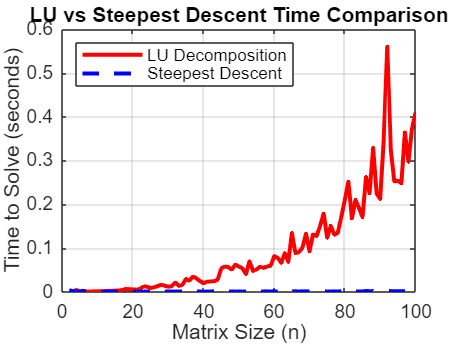

clear all

time_lu = zeros(1, 99);  %99 values from n = 2 to 100
time_sd = zeros(1, 99);

tol = 1e-6;
max_iter = 1000;

for n = 2:100
    idx = n - 1;  %shift index because we start from n=2

    [A, b] = getSystemMatrix(n);

    %LU method
    tic;
    [L, U] = myLU(A);
    y = L \ b;
    x_lu = U \ y;
    time_lu(idx) = toc;

    %steepest Descent
    x0 = zeros(n, 1);
    tic;
    [x_sd, ~] = my_steepest_descent(A, b, x0, tol, max_iter);
    time_sd(idx) = toc;
end

%x-axis for plotting
n_values = 2:100;

%%Plot
figure;
plot(n_values, time_lu, 'r-', 'LineWidth', 2, 'DisplayName', 'LU Decomposition');
hold on;
plot(n_values, time_sd, 'b--', 'LineWidth', 2, 'DisplayName', 'Steepest Descent');
xlabel('Matrix Size (n)');
ylabel('Time to Solve (seconds)');
title('LU vs Steepest Descent Time Comparison');
legend('Location', 'northwest');
grid on;

## Appendix 

function [A,b]= getSystemMatrix(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

%This is my LU code from before
function [L, U] = myLU(A)



[n, m] = size(A);
%make sure our matrix is square
if n ~= m
    error('Matrix A must be square.');
end

%initialize L as the identity matrix and U as a copy of A
L = eye(n);
U = A;

%perform Gaussian elimination without pivoting
for k = 1:n-1
    if U(k,k) == 0
        error('Zero pivot encountered. Factorization fails without pivoting.');
    end
    for i = k+1:n
        %compute the multiplier for row i
        L(i,k) = U(i,k) / U(k,k);
        %update row i of U
        U(i, k:n) = U(i, k:n) - L(i,k) * U(k, k:n);
    end
end

end

Write your steepest descent here.

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, max_iter)
% inputs: A- a symmeteric and positiv definite matrix.
%         b : RHS vector
%        Xguess: Initial guess 
%        tol : tolerance 
%         maxiter:maximum iterations 

%outputs:  x: solution of the system Ax =b
%          iter: number of iterations it took to converge

x = Xguess;
r = A*x - b;
iter = 0;

while norm(r) > tol && iter < max_iter
    step_size = (r'*r) / (r'*A*r);
    x = x - step_size*r;
    r = A*x - b;
    iter = iter + 1;
end

end

